# Kinematics

cd 'F:\Sourcetree Repos\Matlab Personal\Ball Plate Thesis\EE513 Report'
addpath('Kinematics')
printed_trash = evalc('run Variable_Definitions_Report.mlx'); %Run the script to bring all the symbolic definitions into the workspace
clear printed_trash
%sympref('FloatingPointOutput', true);

In order to derive the equations of motion of the ball and plate system, we must first find the velocity and acceleration vectors for arbitrary displacements within the plate's frame of reference. The reason we will describe a majority of our system with respect to the plate frame is that we are interested in the $x $ and $y$ location of the ball relative to the plate. It is quite easy to define these displacements in a plane and quite complicated to attempt to describe the displacemnt of the ball in three dimensional space without using the methods presented here. In addition to the ease of describing the ball's displacment in the plate frame, the plate's inertia tensor


$$I_p^{(2)} = \left\lbrack \begin{array}{ccc}
I_p^{\textrm{xx}}  & 0 & 0\\
0 & I_p^{\textrm{yy}}  & 0\\
0 & 0 & I_p^{\textrm{zz}} 
\end{array}\right\rbrack$$


is diagonal in its own frame. Choosing S2 to describe many of its kinetic quantities is advantageous. 

A schematic of the system is shown in figure 1:

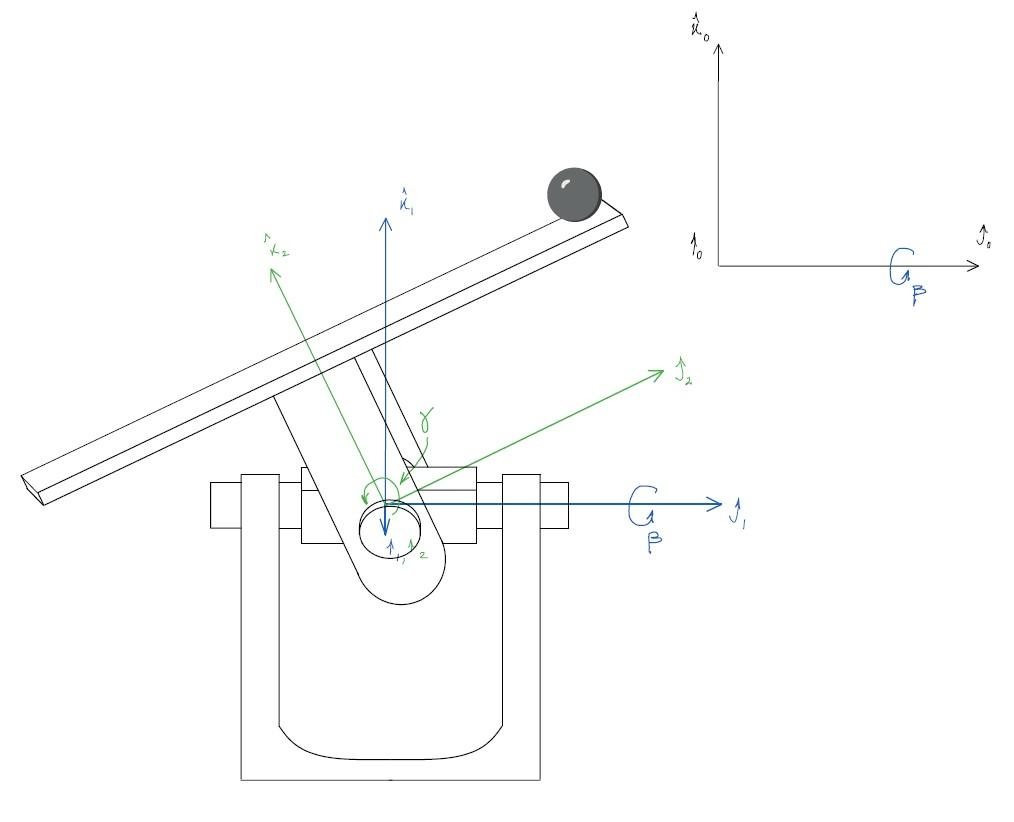

Figure 1: Schematic of the ball and plate system showing the choice of coordinate systems and associated rotation angles. 

The global frame will be denoted S0, the u-joint frame will be denoted S1, and the plate frame will be denoted S2. Frame S0 is the inertial frame of reference - differentiation of kinematic and kinetic quantities will occur with vectors expressed in this frame. In this way, results will be compatible with Newton's laws of motion. The S1 frame is attached to the u-joint block, it is fixed with respect to the joint's axles of rotation. S1 rotates about a shared y axis with S0 through angle $\beta$. Frame S2 rotates about a shared x axis with frame S1 through angle $\gamma$. The rotation matrices associated with these, $R^{01}, R^{10}, R^{12}, and~ R^{21}$ are defined in appendix 1. 

## Notes on Notation for the Kinematic Analysis

- Terms that are bold within a mathematical equation are tensors expressed in direct notation. For these, it is implied that the tensor has been assigned a coordinate system (the coordinate system it is expressed in will be implied by the context). All non bold terms represent the components of a tensor and may be referred to as "component arrays" - these have not been explicitly assigned a basis unless the basis tensors are included in the equation (though from the context one can determine the basis - this is really a formality). A caveat to this is that the basis vectors can only be properly utilized if they are themselves allowed to be considered components of an array. The expression $\mathbf{e^{(0)}}$ represents an array of three components where each is a three dimensional vector: 

                    
$$\mathbf{e^{(0)}} = \left[\matrix{&\mathbf{e^{(0)}_1} \cr  &\mathbf{e^{(0)}_2} \cr &\mathbf{e^{(0)}_3} }~~\right]$$


- Lower indices follow einstein summation convention where no distinction is made between the covariant and contravariant parts of a tensor (all rotations are proper orthogonal). 

- Superscripts label the term and should not be confused with indices

- For rotation matrices, the superscripts indicate the frames being transformed between. The first number indicates the frame that the second frame's basis vectors are being composed in. Or put in another way, the first frame is observing the motion of the second frame's basis vectors and describing them in terms of its own basis vectors. If a set of basis vectors are being composed in another frame, they will be given the clarification "(t)" to indicate that they are now, generally, time varying vectors in that frame. The rotation matrix will multiply the first frames stationairy basis vectors on the left as such:

                    
$$\begin{array}{rl}

\mathbf{e^{(2)}(t)} &=~~ \mathbf{R^{02}(t)e^{(0)}\\[6pt]

\mathbf{e^{(0)}(t)} &=~~ \mathbf{R^{20}(t)e^{(2)} =~~ \mathbf{{R^{02}}^T(t)e^{(2)}


\end{array}$$


- Superscripts on first order tensors indicate the frame in which its components are expressed in. For instance, $\mathbf{r^{(0)}$is the displacement vector whose components are correct when its component array $r^{(0)}_i$ is dotted with the $\mathbf{e^{(0)}_i}$ basis vectors. The vector would not be properly represented if dotted with the $\mathbf{e^{(2)}_i}$ basis vectors.

## Methodology

The positions, velocities,and accelerations for the system are derived below. In finding the velocity of an arbitrary displacement vector in frame S2, we also find the angular velocity of the plate frame 


$$\hat\Omega^{(2)} 

=

\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


expressed in the plate's basis vectors.This, in addition to the linear velocities and accelerations is a very important vector in the kinetic analysis - it helps to describe the angular momenta of the ball and the plate that will be utilized in the sum of the moments in the Newton-Euler kinetic analysis. 

### Position

1. Define an arbitrary displacement vector $\mathbf{r^{(2)}$ whose coordinates are known in frame S2.

2. Use knowledge of how the S2 basis vectors move with respect to the S0 frame to express $\mathbf{r^{(2)}$ in the global basis as $\mathbf{r^{(0)}$.Since the two frames coincide at their origin, this new vector will represent the global displacement vector. 

### Velocity

3. Take the first total time derivative of $\mathbf{r^{(0)}$. This will be the absolute/global velocity of the displacement vector (still expressed in the global basis). 

4. Rotate the basis vectors back to S2 by applying, to the basis vectors only, the inverse of the rotations applied in step 2. In doing this, find our $\dot{\Theta}$ matrices.

5. Obtain our Omega matrix, the angular velocity matrix of the frame S2 as observed in the global frame, expressed in the S2 basis. 

### Acceleration

6. Rotate the velocity vector from step 5 back to the S0 basis. 

7. Take the time derivative of the velocity vector to aquire the global acceleration vector.

8. Rotate the vector back to the S2 basis. 

## Define Arbitrary Displacement Vector $\mathbf{r^{(2)}$

### Step 1

Define $\mathbf{r^{(2)}$, the displacement of a point relative to the origin of S2 expressed in the S2 basis:


$$\begin{array}{rl}

\mathbf{{r}^{(2)}}

&=~~ r_r^{(2)}\mathbf{e_r^{(2)}}\\[6pt]


&=~~ r^{(2)}_1\mathbf{\hat{{\imath}}^{(2)}} +  r^{(2)}_2\mathbf{\hat{{\jmath}}^{(2)}} + r^{(2)}_3\mathbf{\hat{k}^{(2)}}




\end{array}$$


### Step 2

In the S0 frame, the S2 basis vectors are rotating. The two basis share a common origin:


$$\begin{array}{rl}

\mathbf{e_r^{(2)}(t)} &=~~ R^{12}_{rl}(t)R^{01}_{li}(t)\mathbf{e_i^{(0)}} 

&&\text{ $\leftarrow$ S2 basis vectors as seen rotating in the S0 frame. These are expressed in terms of stationairy S0 basis vectors.}\\[6pt]

&=~~ R^{02}_{ri}(t)\mathbf{e_i^{(0)}} 

&&\text{ $\leftarrow$ Combine the sequenced rotations.}

\end{array}
$$


Define $\mathbf{r^{(0)}$, the displacement of a point relative to the origin of S2 expressed in the S0 basis. 


$$\begin{array}{rl}


\mathbf{r^{(0)}} 

&=~~ r_r^{(0)}\mathbf{e_r^{(0)}}\\


&=~~ r^{(0)}_1\mathbf{\hat{{\imath}}^{(0)}} +  r^{(0)}_2\mathbf{\hat{{\jmath}}^{(0)}} + r^{(0)}_3\mathbf{\hat{k}^{(0)}}\\[6pt]



\end{array}$$


Since $\mathbf{r^{(0)}$ and $\mathbf{r^{(2)}$ are tensors representing the same physical entity, they are equivalent. We can utilize this fact along with the knowlege of how the S2 basis vectors rotate in S0 to express $\mathbf{r^{(0)}$ in terms of the components of $\mathbf{r^{(2)}$: 


$$\begin{array}{rl}

\mathbf{r^{(0)}

&=~~ \mathbf{r^{(2)}} 
\\[6pt]



&=~~ r_r^{(2)}\mathbf{e_r^{(2)}(t)} \\ 


\mathbf{r^{(0)}


&=~~r_r^{(2)}R^{12}_{rl}R^{01}_{li}(t)\mathbf{e_i^{(0)}} &&\text { (eq 1)}

\end{array}$$


r0s = R20*r2s;
subs(r0s,symFunVec, symVarVec);

### Final Result: Displacement

Written out fully in terms of the angles $\beta$ and $\gamma$, the arbitrary displacement vector of S2 rotated into S0:


$$r^{(0)} = 

\left\lbrack \begin{array}{c}
r_1^{(2)} \,\mathrm{cos}\left(\beta \right)+r_3^{(2)} \,\mathrm{cos}\left(\gamma \right)\,\mathrm{sin}\left(\beta \right)+r_2^{(2)} \,\mathrm{sin}\left(\beta \right)\,\mathrm{sin}\left(\gamma \right)\\
r_2^{(2)} \,\mathrm{cos}\left(\gamma \right)-r_3^{(2)} \,\mathrm{sin}\left(\gamma \right)\\
r_3^{(2)} \,\mathrm{cos}\left(\beta \right)\,\mathrm{cos}\left(\gamma \right)-r_1^{(2)} \,\mathrm{sin}\left(\beta \right)+r_2^{(2)} \,\mathrm{cos}\left(\beta \right)\,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


Since the frames S2 and S0 always share a common origin, a change in the basis used to represent the displacement in S2 coincides with the description of a displacement in S0. For convenience, we will call $\mathbf{r^{(0)}$ the global displacement vector because they are effectively equivalent. 

## Differentiate $\mathbf{r^{(0)}$ to Obtain Global Velocity Vector 

### Step 3

We take the total time derivative of equation 1.


$$\begin{array}{rl}

\mathbf{v^{(0)}} &=~~

\frac{D{\mathbf{r^{(0)}}}}{Dt}  \\[6pt] 


\mathbf{v^{(0)}}

&=~~\frac{d(r_r^{(2)})}{dt} R_{rl}^{12}(t) R_{li}^{01}(t)\mathbf{e^{(0)}_i}  

+

r_r^{(2)}\frac{d(R_{rl}^{12}(t))}{dt} R_{li}^{01}(t)\mathbf{e^{(0)}_i}   

+ 

r_r^{(2)}R_{rl}^{12}(t) \frac{d(R_{li}^{01}(t)) }{dt} \mathbf{e^{(0)}_i}  

&&\text{ (eq 2)}

\end{array}$$


Equation 2 has three terms on the right hand side:

- This is the relative velocity term - the rate of change of the motion of r within its own frame S2, holding all other terms constant. 

- The rate of change of $\mathbf{r^{(0)}$ that comes from the motion of frame S2 within the frame S1, holding all other terms constant. As if the vector $\mathbf{r^{(0)}$ is constant in S2 and the frame S1 is constant in the global frame S0. 

- The rate of change of $\mathbf{r^{(0)}$ that comes from the motion of frame S1 within S0, holding all other terms constant.

### Step 4

By differentiating the global displacement vector, we have attained the velocity of the vector originally defined in S2 with respect to an inertial reference frame. We are then free to rotate our basis back to the intermediate frame S2. This will express those absolute quantities in a convenient set of basis vectors:

#### **Term (1)**


$$\begin{array}{rl}


\frac{d({r}_r^{(2)})}{dt} R_{rl}^{12}(t) R_{li}^{01}(t)\mathbf{e^{(0)}_i} &=~~ {\dot{r}}^{(2)}_rR_{rl}^{12}(t) R_{li}^{01}(t)\mathbf{e^{(0)}_i}\\[6pt] 



\end{array}$$
      

Here,  $\dot{r}_r^{(2)}$ are the time derivative of the components of $\mathbf{r^{(2)}$, the components of displacement belonging to S2. These components are the $v_{rel}$ terms.   

#### **Term (2)**

 
$$\begin{array}{rl}

r_r^{(2)}\frac{d(R_{rl}^{12}(t))}{dt} R_{li}^{01}(t)\mathbf{e^{(0)}_i} &=~~ r_r^{(2)}\frac{d(R_{rl}^{12}(t))}{dt} R_{li}^{01}(t)\mathbf{e^{(0)}_i(t)}

&&\leftarrow \text{ Replace } \mathbf{e^{(0)}_i}  \text { with } \mathbf{e^{(0)}_i(t)} \text{ to initialize the transformation back to the S2 basis.}\\[6pt]

&=~~ r_r^{(2)}\frac{d(R_{rl}^{12}(t))}{dt} R_{li}^{01}(t)(R_{ip}^{10}(t) R_{ps}^{21}(t)\mathbf{e^{(2)}_s} )\\[6pt]

&=~~ r_r^{(2)}\frac{d(R_{rl}^{12}(t))}{dt} R_{ls}^{21}(t)\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r^{(2)}_r\dot\Theta^{\gamma}_{rp}(t)R_{pl}^{12}(t)R_{ls}^{21}(t)\mathbf{e^{(2)}_s}\\[6pt] 

&=~~r^{(2)}_r \dot\Theta^{\gamma}_{rp}(t)\delta_{ps}\mathbf{e^{(2)}_s}\\[6pt]  

&=~~ r_r^{(2)}\dot\Theta^{\gamma}_{rs}(t)\mathbf{e^{(2)}_s} 

&&\leftarrow \text{ Here  } \dot\Theta^{\gamma}_{rs} \text{ is a skew symmetric matrix containing the rates of change of the Euler angle }\gamma
\end{array}$$


subs(R21d, symFunVec, symVarVec); %Time rate of change of R40 rotation matrix
Theta_d_gam = simplify(R12d*R21); %shows that if this is Theta_d_12 then Theta_d_12*R12 = R12d
subs(Theta_d_gam, symFunVec, symVarVec);

Where:


$$\dot\Theta^{\gamma}

~=~

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & \gamma^˙ \\
0 & -\gamma^˙  & 0
\end{array}\right\rbrack$$


It can be shown that the components $\frac{d(R_{rl}^{12}(t))}{dt} R_{ls}^{21}(t)$ are equivalent to the components $\dot\Theta^{\gamma}_{rs}$. This $\dot\Theta^{\gamma}_{rs}$ matrix was obtained by $\dot\Theta^{\gamma}_{rs} = \dot{R}^{12}_{ri}R^{21}_{is} $. The matrix can also be obtained by factoring out $R^{12}$ from $\dot{R}^{12}$ on the right $\Rightarrow$  $\dot{R}^{12}_{ri} = \dot\Theta^{\gamma}_{rs}R^{12}_{si} $.

#### **Term (3)**


$$\begin{array}{rl}

r_r^{(2)}R_{rl}^{12}(t) \frac{d(R_{li}^{01}(t)) }{dt} \mathbf{e^{(2)}_i} &=~~ 
r_r^{(2)}R_{rl}^{12}(t) \frac{d(R_{li}^{01}(t)) }{dt} R^{10}_{ip}(t)R^{21}_{ps}(t)\mathbf{e^{(0)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)R^{01}_{qi}(t)R^{10}_{ip}(t)R^{21}_{ps}(t)\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)\delta_{qp}R^{21}_{ps}(t)\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)R^{21}_{qs}(t)\mathbf{e^{(2)}_s}\\[6pt]


\end{array}$$


Theta_d_beta = simplify(R01d*R10);
subs(Theta_d_beta, symFunVec, symVarVec);

Where: 


$$\dot\Theta^{\beta}_{rs}~ =~

\left\lbrack \begin{array}{ccc}
0 & 0 & -\beta^˙ \\
0 & 0 & 0\\
\beta^˙  & 0 & 0
\end{array}\right\rbrack$$


### Step 5

Terms 1-3 are now elements of $\mathbf{v^{(2)}$ since the basis vectors constained in them belong to S2. We will group these terms to find the $\mathbf{\Omega^{(2)}}$ 3x3 matrix. This will be the angular velocity matrix of the S2 frame's motion in S0. Left multiplying a 3x1 vector **r** by this 3x3 matrix is equivalent to the cross product between the $\mathbf{\Omega}$ *vector* and **r**:


$$\begin{array}{rl}

\mathbf{{v}^{(0)}} 

&=~~ \mathbf{{{v}^{(2)}}}&&\text{(1)} \\[6pt]

{{v}^{(2)}_s}\mathbf{e^{(2)}_s} 
&=~~ {\dot{r}_s^{(2)}}\mathbf{e^{(2)}_s} 
+~ r_r^{(2)}\dot\Theta^{\gamma}_{rs}(t)\mathbf{e^{(2)}_s} 
+~ r_r^{(5)}R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)R^{21}_{qs}(t)\mathbf{e^{(2)}_s} 
\\[6pt]



&=~~ {\dot{r}_s^{(2)}}\mathbf{e^{(2)}_s}
+~ r_r^{(2)}(\dot\Theta^{\gamma}_{rs}(t)   
+~ R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)R^{21}_{qs}(t))\mathbf{e^{(2)}_s}
\\[6pt]


{{v}^{(2)}_s}
&=~~ {\dot{r}_s^{(2)}}
+~ r_r^{(5)}(\dot\Theta^{\gamma}_{rs}(t)  
+~ R_{rl}^{12}(t) \dot\Theta^{\beta}_{lq}(t)R^{21}_{qs}(t))
\\[6pt]

\mathbf{{{{v}}^{(2)}}^T} 
&=~~ \mathbf{{\dot{r}^{(2)}}^T}
+~ \mathbf{{r^{(2)}}^T}(\dot\Theta^{\gamma}(t) +~ R^{12}(t) \dot\Theta^{\beta}(t)R^{21}(t))
&&\text{(2)}\\[6pt]

\mathbf{{{v}}^{(2)}} 
&=~~ \mathbf{{\dot{r}^{(2)}}}
+~ (\dot\Theta^{\gamma}(t) +~ R^{12}(t) \dot\Theta^{\beta}(t)R^{21}(t))^T\mathbf{{r^{(2)}}}
&&\text{(3)}\\[6pt]


\end{array}$$


We have arrived at


$$\begin{array}{rl}

\mathbf{v^{(2)}} 
&=~~  \mathbf{\dot{r}^{(2)}}
+~ \Omega^{(2)}(t\mathbf{){r^{(2)}}}
&&\text{(eq 3)}\\[6pt]

\end{array}$$


Where


$$
\Omega^{(2)}(t) ~=~~  (\dot\Theta^{\gamma}(t)+~ R^{12}(t) \dot\Theta^{\beta}(t)R^{21}(t))^T 
$$


In general, it's components are the global angular velocities of the intermediate frame S2 expressed in its own basis.


$$\Omega^{(2)}(t) ~=~~ 

\left\lbrack \begin{array}{ccc}
0 & -\omega_z  & \omega_y \\
\omega_z  & 0 & -\omega_x \\
-\omega_y  & \omega_x  & 0
\end{array}\right\rbrack$$


subs(Omega2ms, symFunVec, symVarVec); % Show the cap Omega matrix components

At (1), the invariance of the velocity vector under a coordinate transformation is acknowledged. Though we differentiated r(0) to get v(0), we can write v(0) in the S2 basis without changing what the vector represents, the global velocity of the global displacement vector. 

At (2) we switch to matrix notation from indicial notation and more readily observe that throughout this analysis, the vector r has been a transpose (the dot product of its components with its basis vector array requires that it be transposed). At (3) we take the transpose of both sides to get the $\Theta$ matrices to multiply **r** (not its transpose) on the left. We then, at equation 3, rename the terms in the paranthesis $\Omega^{(2)}(t)$- this is the angular velocity of the S2 frame within the global frame; its components, however, are expressed in the S2 basis. Here we attain the velocity equation, in an absolute sense, for an arbitrary displacement vector in the rotating frame S2, expressed in the S2 basis.

It can be seen in equation 3 that no rotation matrices multiply $\dot\Theta^{\gamma}(t)$. This is because the axis of rotation for $\gamma$ is fixed in the S2 frame - there is no transformation required to determine the direction of the contribution from $\dot\gamma
$ to the frames angular velocity vector, its always in the frame's $\mathbf{\hat{{\jmath}$ direction. Two matrices multiply $\dot\Theta^{\beta}(t)$; one on the left and one on the right. This turns out to be a similarity transform on $\dot\Theta^{\beta}(t)$whose components are expressed in the S1 basis. The axis of rotation for $\beta$ is moving with respect to S2 and therefore its contribution to the frames angular velocity vector is also changing direction - this is realized in the similarity transform between the two frames. 

### Equivalence of the cross product and matrix multiplication for Capitol Omega

Equation 3 can be rewritten as


$$\mathbf{{v}^{(2)}} 
=~~ \mathbf{{\dot{r}^{(2)}}}
+~ \mathbf{\hat\Omega^{(2)}(t)\times{r^{(2)}}}
$$


where $ \mathbf{\hat\Omega^{(2)}(t)$is a vector containing the angular velocities from $\Omega^{(2)}(t)$


$$ \hat\Omega^{(2)} = 

\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


and matrix multiplication has been exchanged for the cross product. 

Our derivation of the $\Omega^{(2)}(t)$ matrix from differentiation of rotating vectors led us to knowledge of the components of the $ \mathbf{\hat\Omega^{(2)}(t)$vector. This vector is more useful to our kinetic analysis than the matrix because the angular momenta in the system are defined in terms of the vector and not the matrix. 

subs(Omega2vs, symFunVec, symVarVec);

### Final Result: Global Velocity and Angular Velocity

The global angular velocity matrix of the plate in terms of u-joint angles - S2 basis:

Omega2ms = simplify((Theta_d_gam + R12*Theta_d_beta*R21).');
subs(Omega2ms, symFunVec, symVarVec);


$$\Omega^{(2)} = 

\left\lbrack \begin{array}{ccc}
0 & \beta^˙ \,\mathrm{sin}\left(\gamma \right) & \beta^˙ \,\mathrm{cos}\left(\gamma \right)\\
-\beta^˙ \,\mathrm{sin}\left(\gamma \right) & 0 & -\gamma^˙ \\
-\beta^˙ \,\mathrm{cos}\left(\gamma \right) & \gamma^˙  & 0
\end{array}\right\rbrack$$


The global angular velocity vector of the plate in terms of u-joint angles - S2 basis:

 Omega2vs(1) = Omega2ms(3,2); 
 Omega2vs(2) = Omega2ms(1,3);
 Omega2vs(3) = Omega2ms(2,1);
 omega_p = subs(Omega2vs, symFunVec, symVarVec); %This produces what I got in my hand calculations!


$$ \hat\Omega^{(2)}

~=~ 

\left\lbrack \begin{array}{c}
\gamma^˙ \\
\beta^˙ \,\mathrm{cos}\left(\gamma \right)\\
-\beta^˙ \,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


The global velocity vector of an arbitrary displacement within frame S2 written in the S2 basis:

 v2s =  diff(r2s,t) + Omega2ms*r2s; %This creates the symvar for the global velocity vector expressed in the S2 Basis
 subs(v2s, symFunVec, symVarVec);
 


$$v^{(2)} 

~=~

\left\lbrack \begin{array}{c}
{\dot{r} }_1^{(2)} +\beta^˙ \,r_2^{(2)}  \,\mathrm{sin}\left(\gamma \right)+\beta^˙ \,r_3^{(2)}  \,\mathrm{cos}\left(\gamma \right)\\
{\dot{r} }_2^{(2)}  -\gamma^˙ \,r_3^{(2)}  -\beta^˙ \,r_1^{(2)}  \,\mathrm{sin}\left(\gamma \right)\\
{\dot{r} }_3^{(2)}  +\gamma^˙ \,r_2^{(2)}  -\beta^˙ \,r_1^{(2)}  \,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


## Differentiate $\mathbf{v^{(0)}$ to Obtain Global Acceleration Vector

### Step 6

Rotate $\mathbf{v^{(2)}$ back to the S0 basis, obtaining $\mathbf{v^{(0)}$. 


$$\begin{array}{rl}

\mathbf{v^{(0)}} &=~~ R^{20}\mathbf{v^{(2)}}\\[6pt]

&=~~ R^{20}(\mathbf{\dot{r}^{(2)}}
+~ \Omega^{(2)}(t\mathbf{){r^{(2)}}})


\end{array}$$


### Step 7

Differentiate $\mathbf{v^{(0)}$ to obtain the global acceleration vector. 


$$\begin{array}{rl}

\mathbf{a^{(0)}} &=~~ \mathbf\frac{{D{v}^{(0)}}}{Dt}
&=~~  \dot{R}^{20}(\mathbf\dot{r}^{(2)}
+~ \Omega^{(2)}(t)\mathbf r^{(2)})


+~ R^{20}(\mathbf\ddot{r}^{(2)}

+~ \dot\Omega^{(2)}(t){\mathbf r^{(2)}}

+~ \Omega^{(2)}(t){\mathbf\dot{r}^{(2)}})
\\[6pt]


\end{array}$$


 a0s = diff(R20*v2s,t);
 subs(a0s, symFunVec, symVarVec);

### Step 8

Rotate back to the S2 basis to describe the global acceleration in the plate's basis. 


$$\begin{array}{rl}

\mathbf{a^{(2)}}&=~~ R^{02}\mathbf\frac{{D{v}^{(0)}}}{Dt}
&=~~ R^{02}( \dot{R}^{20}(\mathbf\dot{r}^{(2)}
+~ \Omega^{(2)}(t)\mathbf r^{(2)})


+~ R^{20}(\mathbf\ddot{r}^{(2)}

+~ \dot\Omega^{(2)}(t){\mathbf r^{(2)}}

+~ \Omega^{(2)}(t){\mathbf\dot{r}^{(2)}}))
\\[6pt]


\end{array}$$


### Final Result: Global Acceleration

a2s = simplify(R02*a0s);


$$\mathbf{a^{(2)}} = 

\left\lbrack \begin{array}{c}
{\ddot{r} }_1 -{\beta^˙ }^2 \,r_1 +\beta^¨ \,r_2 \,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,{\dot{r} }_2 \,\mathrm{sin}\left(\gamma \right)+\beta^¨ \,r_3 \,\mathrm{cos}\left(\gamma \right)+2\,\beta^˙ \,{\dot{r} }_3 \,\mathrm{cos}\left(\gamma \right)+2\,\beta^˙ \,\gamma^˙ \,r_2 \,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\gamma^˙ \,r_3 \,\mathrm{sin}\left(\gamma \right)\\
{\ddot{r} }_2 -\gamma^¨ \,r_3 -2\,\gamma^˙ \,{\dot{r} }_3 -{\beta^˙ }^2 \,r_2 -{\gamma^˙ }^2 \,r_2 -\beta^¨ \,r_1 \,\mathrm{sin}\left(\gamma \right)-2\,\beta^˙ \,{\dot{r} }_1 \,\mathrm{sin}\left(\gamma \right)+{\beta^˙ }^2 \,r_2 \,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,r_3 \,\mathrm{sin}\left(2\,\gamma \right)}{2}\\
{\ddot{r} }_3 +\gamma^¨ \,r_2 +2\,\gamma^˙ \,{\dot{r} }_2 -{\gamma^˙ }^2 \,r_3 -{\beta^˙ }^2 \,r_3 \,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,r_2 \,\mathrm{sin}\left(2\,\gamma \right)}{2}-\beta^¨ \,r_1 \,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,{\dot{r} }_1 \,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


# Ball and Plate Kinematics

Now, we must substitute the arbitrary displacement vector components from the kinematic analysis for meaningful displacement vectors of our system. We will choose the centers of mass of the ball and the plate. In doing so, we will obtain the global velocities and accelerations of the mass elements of our system for use in force analysis. 

## Ball Kinematics

We will substitute in the displacement vector to the ball's center of mass defined in the plate's basis with the arbitrary displacment vector $\mathbf{r^{(2)}$. Any differentiated component of $\mathbf{r^{(2)}$ must become a differentiated component of the substituded displacement vector. The ball's displacement vector in the plate frame will contain the two variables that we will later use as state variables - its x and y components. These describe the position of the ball with respect to the surface of the plate. The z postion of the ball in the plate frame, $z_b$, is constant because the ball never leaves the plate. 


$$r_b^{(2)} ~=~ 

\left\lbrack \begin{array}{c}
x\\
y\\
z_b 
\end{array}\right\rbrack$$


Substituting  $r_b^{(2)}$ into the velocity equation, we get:

vb2s = subs(v2s, symFunVec_r, symFunVec_rb);
subs(vb2s, symFunVec, symVarVec);


$$v_b^{(2)}

 ~=~ 

\left\lbrack \begin{array}{c}
\dot{x} +\beta^˙ \,z_b \,\mathrm{cos}\left(\gamma \right)+\beta^˙ \,y\,\mathrm{sin}\left(\gamma \right)\\
\dot{y} -\gamma^˙ \,z_b -\beta^˙ \,x\,\mathrm{sin}\left(\gamma \right)\\
\gamma^˙ \,y-\beta^˙ \,x\,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


Substituting $r_b^{(2)}$ into the acceleration equation, we get:

ab2s = subs(a2s, symFunVec_r, symFunVec_rb);
subs(ab2s,symFunVec, symVarVec);


$$a_b^{(2)}

 ~=~ 

\left\lbrack \begin{array}{c}
\ddot{x} -{\beta^˙ }^2 \,x+\beta^¨ \,z_b \,\mathrm{cos}\left(\gamma \right)+\beta^¨ \,y\,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,\dot{y} \,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,\gamma^˙ \,y\,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\gamma^˙ \,z_b \,\mathrm{sin}\left(\gamma \right)\\
\ddot{y} -\gamma^¨ \,z_b -{\beta^˙ }^2 \,y-{\gamma^˙ }^2 \,y-\beta^¨ \,x\,\mathrm{sin}\left(\gamma \right)-2\,\beta^˙ \,\dot{x} \,\mathrm{sin}\left(\gamma \right)+{\beta^˙ }^2 \,y\,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,z_b \,\mathrm{sin}\left(2\,\gamma \right)}{2}\\
\gamma^¨ \,y+2\,\gamma^˙ \,\dot{y} -{\gamma^˙ }^2 \,z_b -\beta^¨ \,x\,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\dot{x} \,\mathrm{cos}\left(\gamma \right)-{\beta^˙ }^2 \,z_b \,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,y\,\mathrm{sin}\left(2\,\gamma \right)}{2}
\end{array}\right\rbrack$$


## Rolling Without Slip Constraint

This condition will relate $\Psi_x
$ and $\Psi_y$ of $\Psi^{(2)}$ to $\dot{y}$ and $\dot{x}$. The vector $\Psi^{(2)}$ is defined to be the ball's angular velocity within the plate frame:

subs(Psi2vs, symFunVec, symVarVec);


$$\Psi^{(2)}~=~

\left\lbrack \begin{array}{c}
\psi_x \\
\psi_y \\
\psi_z 
\end{array}\right\rbrack$$


We assume that the ball is rolling about the plate's surface without slipping. This assumption allows us to relate $\Psi^{(2)}$ to the relative velocity of the ball $\dot{r}_b^{(2)} $ through the cross product


$$\dot{r}_b^{(2)} ~=~  

\left\lbrack \begin{array}{c}
\dot{x}\\
\dot{y}\\
0
\end{array}\right\rbrack

~=~ 

\Psi^{(2)} \times arm_b^{(2)}$$


where $arm_b^{(2)}$ is the moment arm between the ball's contact point with the plate and the ball's center of mass expressed in the plate frame.


$$arm_b^{(2)} = \left\lbrack \begin{array}{c}
0\\
0\\
r_b 
\end{array}\right\rbrack$$


In doing this, we can express the ball's angular velocity in terms of variables we desire for our state vector, $\dot{y}$ and $\dot{x}$. Solving for the angular velocity components in the above cross product yields:

constr_eqn_rws = diff(rb2s,t,1) == cross(Psi2vs, armb2s); %Contraint Equation Rolling Without Slip (RWS)
subs(constr_eqn_rws, symFunVec, symVarVec);
Psi2vs(1) = rhs(isolate(constr_eqn_rws(2), Psi2vs(1)));
Psi2vs(2) = rhs(isolate(constr_eqn_rws(1), Psi2vs(2)));
subs(Psi2vs,symFunVec, symVarVec);


$$\Psi^{(2)} ~=~

\left\lbrack \begin{array}{c}
-\frac{\dot{y} }{r_b }\\
\frac{\dot{x} }{r_b }\\
\psi_z 
\end{array}\right\rbrack$$


Here, $\Psi_z$ is leftover, but it will be irrelevant to the dynamics of the ball that we will be concerned with.  

## Ball Kinematics

We will substitute in the displacement vector to the plate's center of mass defined in its own basis with the arbitrary displacment vector $\mathbf{r^{(2)}$. Just as before,any differentiated component of $\mathbf{r^{(2)}$ must become a differentiated component of the substituded displacement vector. The plate's displacement vector in its own frame is a constant vector with only a z component, as we assume that the plate's center of mass is located directly above the origin of the S2 frame. Since this vector is utilized as a moment arm in the kinetic analysis later, it is denoted $arm_p^{(2)}$:


$$arm_p^{(2)} ~=~

\left\lbrack \begin{array}{c}
0\\
0\\
z_p 
\end{array}\right\rbrack$$


Substituting  $arm_p^{(2)}$ into the velocity equation, we get:

vp2s = subs(v2s, symFunVec_r, symFunVec_rp);
subs(vp2s, symFunVec, symVarVec);


$$v_p^{(2)} ~=~ 

\left\lbrack \begin{array}{c}
\beta^˙ \,z_p \,\mathrm{cos}\left(\gamma \right)\\
-\gamma^˙ \,z_p \\
0
\end{array}\right\rbrack$$


Substituting  $arm_p^{(2)}$ into the acceleration equation, we get:

ap2s = subs(a2s, symFunVec_r, symFunVec_rp);
subs(ap2s, symFunVec, symVarVec);


$$a_p^{(2)} ~=~ 

\left\lbrack \begin{array}{c}
\beta^¨ \,z_p \,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\gamma^˙ \,z_p \,\mathrm{sin}\left(\gamma \right)\\
-\frac{\mathrm{sin}\left(2\,\gamma \right)\,{\beta^˙ }^2 \,z_p }{2}-\gamma^¨ \,z_p \\
-{\mathrm{cos}\left(\gamma \right)}^2 \,{\beta^˙ }^2 \,z_p -{\gamma^˙ }^2 \,z_p 
\end{array}\right\rbrack$$
